# Nenana Engineering Challenge (1/2)

**Before you get started:**

This live script is intended to be used with the code visible and output inline. On **View** tab of the MATLAB toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

 Interacting with this live script will build some familiarity with MATLAB, as concepts and commands are introduced together. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2 hour online tutorial that teaches the essentials of MATLAB.

  For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one, including running the code blocks in it.

## 1. Identify the Need.

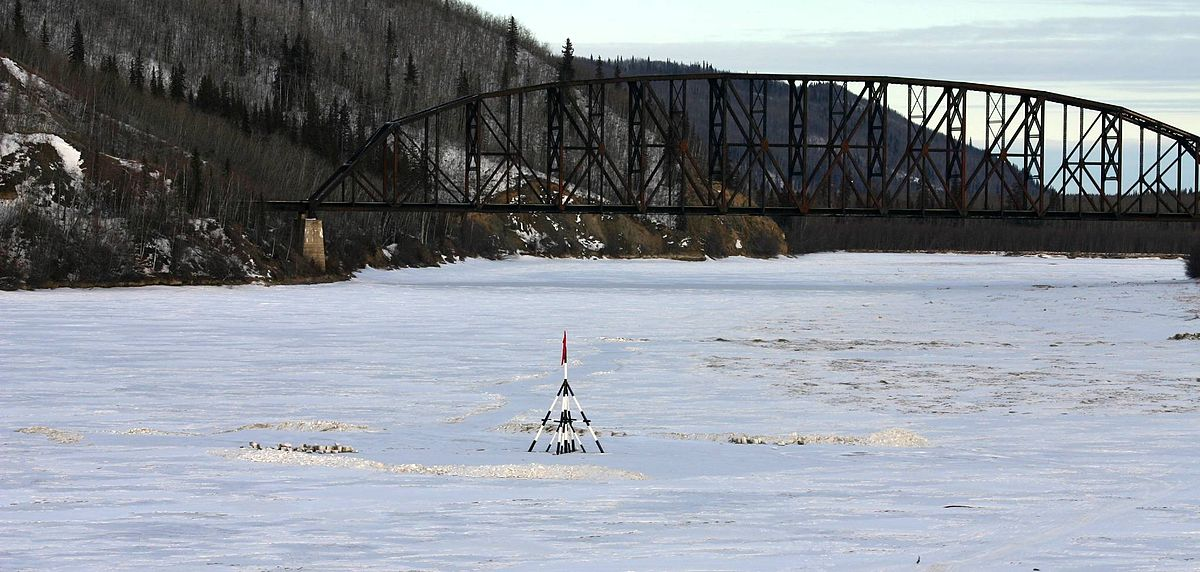

(Photo source: [https://commons.wikimedia.org/wiki/File:Tanana_River_in_Nenana.jpg](https://commons.wikimedia.org/wiki/File:Tanana_River_in_Nenana.jpg))

The Nenana Ice Classic is an annual event that takes place in Nenana, Alaska. It is a guessing game where people try to predict the exact time when the ice on the Tanana River will break up in the spring. 

Participants purchase tickets for a small fee and guess the month, day, hour, and minute when the tripod, which is placed on the frozen river, will move and stop the clock. The tripod is connected to a wire that is attached to a clock on the riverbank. When the ice starts to melt, the tripod moves with the current, and when it falls through the ice, the wire pulls a rope that stops the clock. 

You can find the exact dates and times of ice breakup have been collected since 1917 and reported on a calendar in the [Nenana Ice Classic Brochure](https://www.nenanaakiceclassic.com/brochures) on the [Nenana Ice Classic Website](https://www.nenanaakiceclassic.com/). 

To explore this topic further, read [Nenana Ice Classic: Breaking up is hard to do predictably | National Snow and Ice Data Center (nsidc.org)](https://nsidc.org/news-analyses/news-stories/nenana-ice-classic-breaking-hard-do-predictably)

 **Reflect**.  

Can you use the data of the exact dates and times of ice breakup from 1917-2021 to predict the exact time when the Tanana River will break? Can you use the data to determine impacts of climate change?

Identify the Need: What is the problem to solve? What do we want to design? Who is it for? What do we want to accomplish? What is our goal?

## 

## 2. Research the Problem. 

### Collect Data

The National Snow and Ice Data Center provides the tabulated version of the exact times of breakup from the [Nenana Ice Classic Brochure](https://www.nenanaakiceclassic.com/brochures) in the NenanIceClassic1917-2021.csv file from 1917 until 2021. 

#### i. Import Data

In MATLAB, we can use Live Tasks which are simple point-and-click interfaces that can be added to a live script to perform a specific set of operations. You can add tasks to live scripts to explore parameters and automatically generate code. Learn more about [Interactive Live Tasks](https://www.mathworks.com/help/matlab/matlab_prog/add-live-editor-tasks-to-a-live-script.html) here. 

  **Try**. Import Data

% Insert Import Data Task here. 



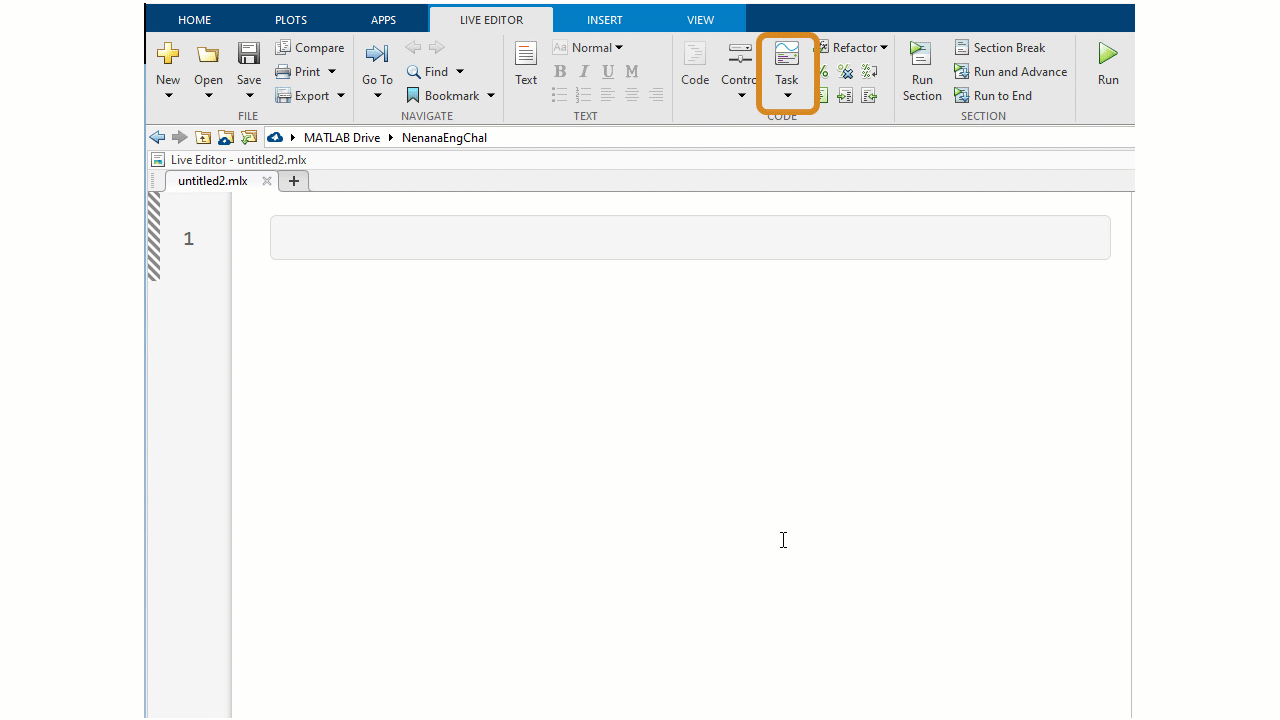

- Go to **Live Editor** Tab.

- Navigate to **Task** dropdown menu.

- Select **Import Data** Task

- Choose NenanIceClassic1917-2021.csv file from location on your computer.

- Specify imported variable options as **Column vectors.**

*Data Source: Nenana Ice Classic. Edited by W. N. Meier and C. F. Dewes. 2020. Nenana Ice Classic: Tanana River Ice Annual Breakup Dates, Version 2. [1917-2021]. Boulder, Colorado USA. NASA National Snow and Ice Data Center Distributed Active Archive Center. https://doi.org/10.5067/CAQ58H42LQY2. April 26, 2023.*

#### ii. Plot Data

You have imported six column vectors: Year, DecimalDayOfYear, Month, Day, Time, and Month in Numbers. You can use the scatter command,  scatter`(`[`X`](https://www.mathworks.com/help/matlab/ref/plot.html?searchHighlight=plot&s_tid=srchtitle_support_results_1_plot#mw_6748a9ec-33eb-483b-b8f1-919954dfae40)`,`[`Y`](https://www.mathworks.com/help/matlab/ref/plot.html?searchHighlight=plot&s_tid=srchtitle_support_results_1_plot#mw_52c5aef5-9f3e-4d29-b95f-485d73104bec)`)` to create  a **scatter** plot with circular markers at the locations specified by the vectors x and y.

  **Try**. Use the [scatter](https://www.mathworks.com/help/matlab/ref/scatter.html?s_tid=srchtitle_site_search_1_scatter) command to create a scatter plot of the DecimalDayOfYear vs. Year, in the code space below. You can copy the code from above and paste it in the code block below.

% Try scatter command here. 
scatter(Year,DecimalDayOfYear)

 Run this code block by clicking the    **Run Section** button in the **Live Editor** tab.

You can label the x-axis, y-axis using the [xlabel](https://www.mathworks.com/help/matlab/ref/xlabel.html?searchHighlight=xlabel&s_tid=srchtitle_support_results_1_xlabel) and [ylabel](https://www.mathworks.com/help/matlab/ref/ylabel.html?s_tid=doc_ta) commands. The xlabel and ylabel commands, `xlabel``(`[`txt`](https://www.mathworks.com/help/matlab/ref/xlabel.html?searchHighlight=xlabel&s_tid=srchtitle_support_results_1_xlabel#btpmg0w-1_sep_shared-txt)`),ylabel(`[`txt`](https://www.mathworks.com/help/matlab/ref/xlabel.html?searchHighlight=xlabel&s_tid=srchtitle_support_results_1_xlabel#btpmg0w-1_sep_shared-txt)`)` label the *x*-axis and the y-axis of the current axes. 

  **Try**. Label the axes using the [xlabel](https://www.mathworks.com/help/matlab/ref/xlabel.html?searchHighlight=xlabel&s_tid=srchtitle_support_results_1_xlabel) and [ylabel](https://www.mathworks.com/help/matlab/ref/ylabel.html?s_tid=doc_ta) commands.  You can copy the code from above and paste it in the code block below.

% Try xlabel and ylabel commands here.


 Run this code block by clicking the    **Run Section** button in the **Live Editor** tab.

## 

## `3`. Imagine: Develop Possible Solutions. 

Historically, most people have used a linear model to fit the Nenana Ice Classic data. Use the button below to generate a linear fit for the entire data set.

 
linearplot

 **Reflect**.  

What does the slope of the Decimal Day Of Year vs. Year represent? What are the implications of the slope being positive or negative?

In the [Nenana Ice Classic: Breaking up is hard to do predictably | National Snow and Ice Data Center (nsidc.org)](https://nsidc.org/news-analyses/news-stories/nenana-ice-classic-breaking-hard-do-predictably) publication, scientists suggest that one linear fit for the entire 1917-2021 range of data may not make sense because there may be multiple trends over the time range. The different trends in the Nenana Ice Classic data for ice breakup times happen because of a few reasons:

- **Weather Changes**

- **Natural Differences**

- **Sometimes It's Just Luck**

- **Nature Can Be Tricky**

- **Data Changes**

So, when you see that the latest ice breakups are mostly in the early years and the earliest ones are in the later years, it's because of these reasons. It's not always easy to predict when the ice will break because nature can be unpredictable.

Regenerate the scatter plot from above to visualize the data set.

  **Try**. Use the [scatter](https://www.mathworks.com/help/matlab/ref/scatter.html?s_tid=srchtitle_site_search_1_scatter) command to create a scatter plot of the DecimalDayOfYear vs. Year, in the code space below.  You can copy the code from above and paste it in the code block below.

% Try scatter command here.



 Run this code block by clicking the    **Run Section** button in the **Live Editor** tab.

 **Reflect**.  

        Which date ranges seem to indicate the multiple trends within the data set?

### [Nenana4_6](matlab:open('./Nenana4_6.mlx'))

% Do not edit below


function linearplot
%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 6);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["year", "decimaldayofyear", "Month", "Day", "Time", "Month_num"];
opts.VariableTypes = ["double", "double", "categorical", "double", "string", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "Time", "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Month", "Time"], "EmptyFieldRule", "auto");

% Import the data
NenanaIceClassic_1917_2021 = readtable("NenanaIceClassic_1917-2021.csv", opts);

% Clear temporary variables
clear opts

% Fit a linear model to data 
[xData, yData] = prepareCurveData(NenanaIceClassic_1917_2021.year, NenanaIceClassic_1917_2021.decimaldayofyear );

% Set up fittype and options.
ft = fittype( 'poly1' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft );

% Plot fit with data.
figure( 'Name', '1917 - 2021' );
h = plot( fitresult, xData, yData );
legend( h, 'DecimalDayOfYear vs. Year', '1917 - 2021', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'Year', 'Interpreter', 'none' );
ylabel( 'DecimalDayOfYear', 'Interpreter', 'none' );
grid on
end